# Ejercicio 3.04  

Usa la Robotics System Toolbox v2.2

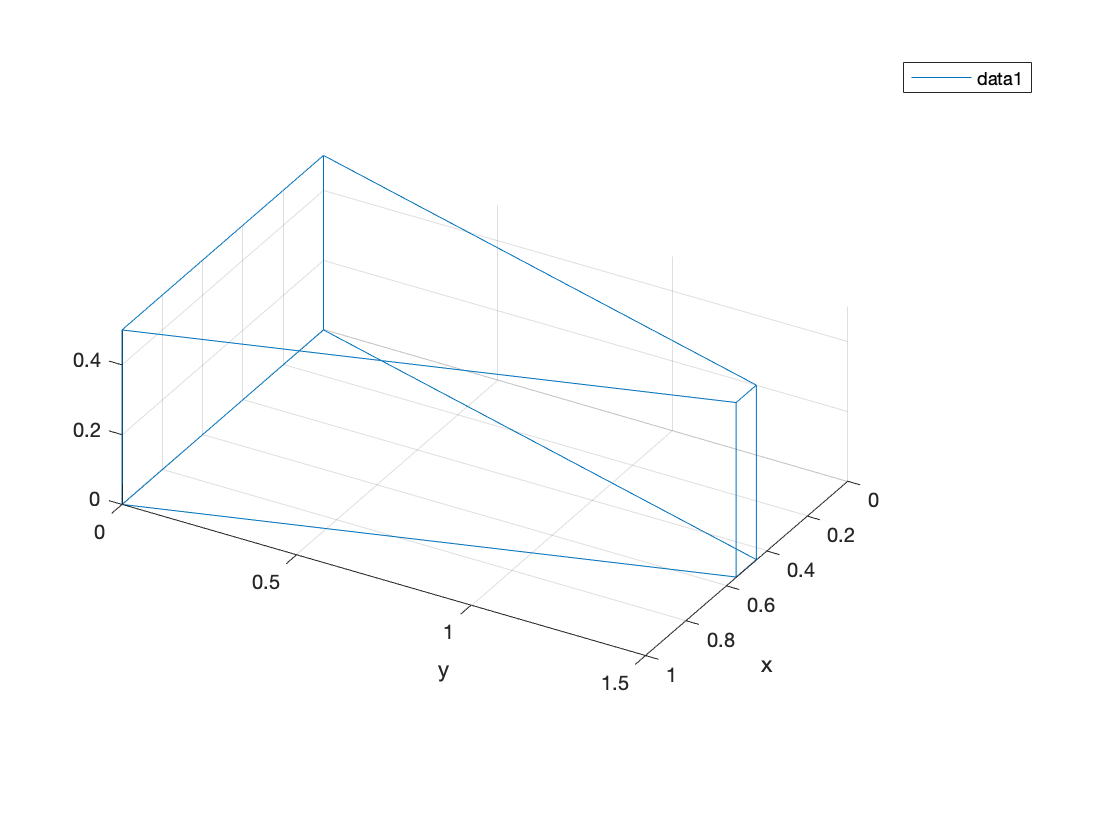


% Escogemos el sólido de referencia:
P=psolido;

% se puede representar con plot3:
Pp=P'; plot3(Pp(:,1),Pp(:,2),Pp(:,3))
axis equal; grid
view(120,30); hold on, xlabel('x'); ylabel('y'); legend

Hacemos tres giros independientes, respecto a X,Y,Z de ejes fijos.

% Giro 1:
T1=axang2tform([1 0 0 pi/2])

T1 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000


quat = tform2quat(T1)

quat =     0.7071    0.7071         0         0


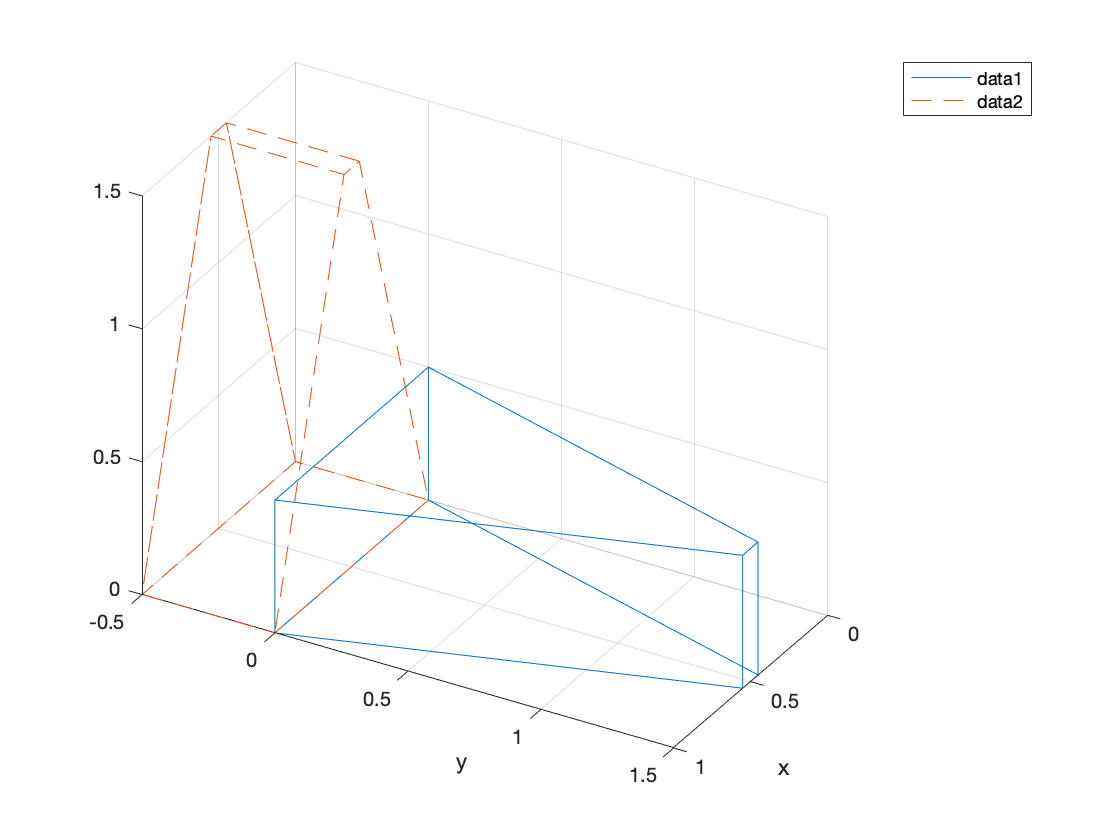

% en cartesianas:
% P = T1(1:3,1:3) * P;
% Pp=P'; plot3(Pp(:,1),Pp(:,2),Pp(:,3))

% en homogéneas:
% Los pasamos a coodenadas homogéneas:
Ph = cart2hom(P');
Ph=Ph';
Ph  = T1 * Ph;
Pp=Ph'; 
plot3(Pp(:,1),Pp(:,2),Pp(:,3),'--')

% Giro 2:
P=psolido;
T1=axang2tform([0 1 0 pi/2]);
quat = tform2quat(T1)

quat =     0.7071         0    0.7071         0


P = T1(1:3,1:3) * P;
Pp=P'; 
plot3(Pp(:,1),Pp(:,2),Pp(:,3))

% Giro 3:
P=psolido;
T1=axang2tform([0 0 1 pi/2]);
quat = tform2quat(T1)

quat =     0.7071         0         0    0.7071


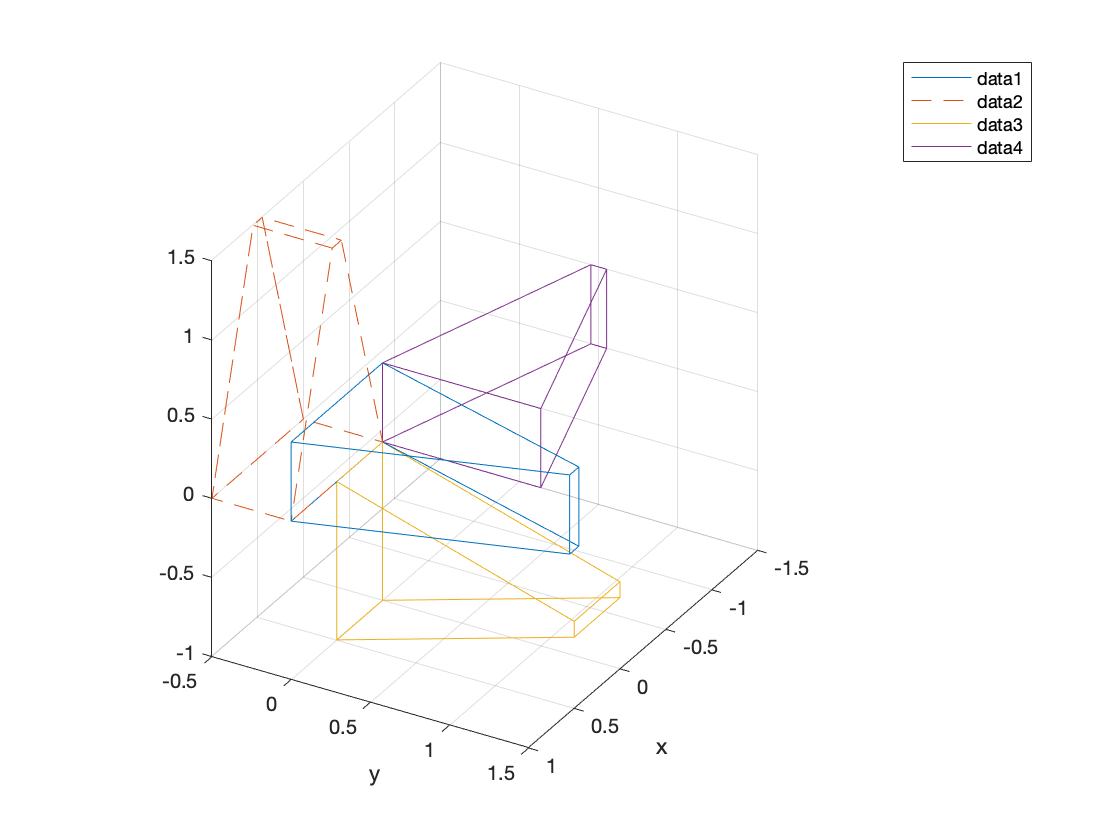

P = T1(1:3,1:3) * P;
Pp=P'; plot3(Pp(:,1),Pp(:,2),Pp(:,3))

En cambio ahora hacemos tres sucesivas rotaciones XYZ, definidas respecto a ejes fijos:

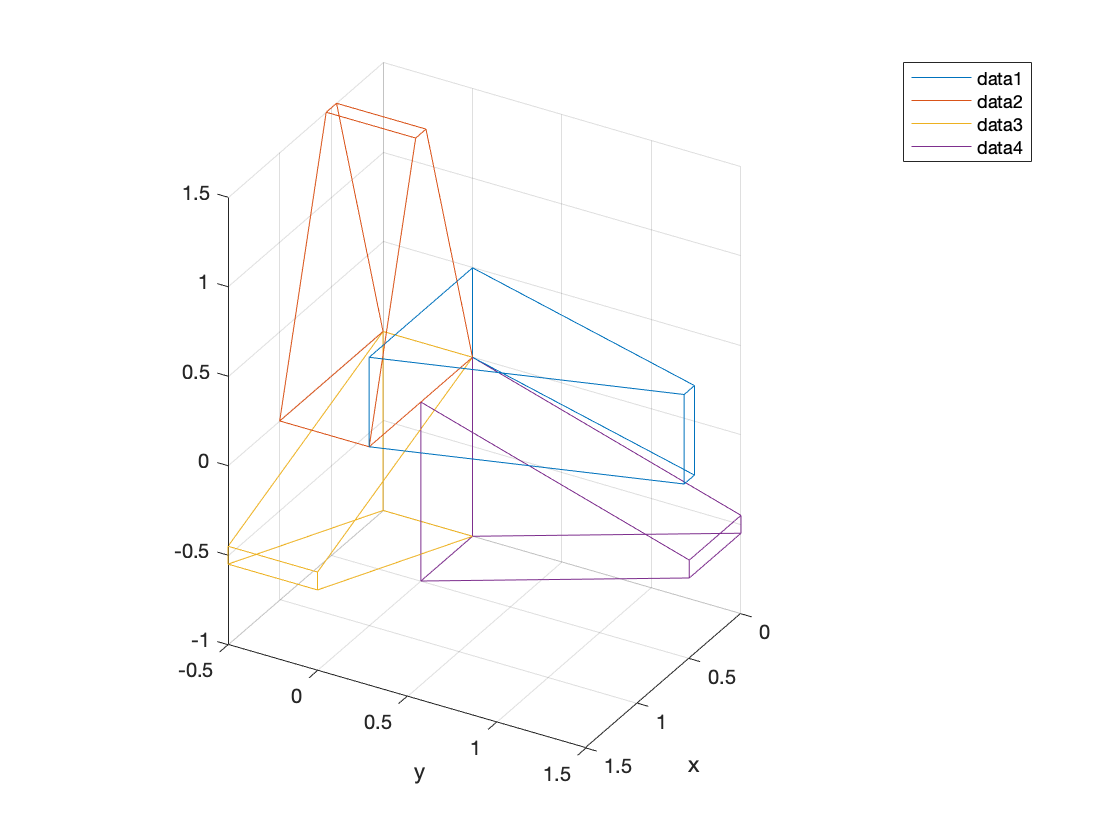

figure;
P=psolido;
Pp=P'; plot3(Pp(:,1),Pp(:,2)',Pp(:,3)')
axis equal; grid
view(120,30); hold on
xlabel('x'); ylabel('y'); legend

% Lo calculamos en cartesianas:
% Giro 1:
T1=axang2tform([1 0 0 pi/2]);
P = T1(1:3,1:3) * P;
Pp=P'; plot3(Pp(:,1),Pp(:,2),Pp(:,3))
% Giro 2:
T1=axang2tform([0 1 0 pi/2]);
P = T1(1:3,1:3) * P;
Pp=P'; plot3(Pp(:,1),Pp(:,2),Pp(:,3))
% Giro 3:
T1=axang2tform([0 0 1 pi/2]);
P = T1(1:3,1:3) * P;
Pp=P'; plot3(Pp(:,1),Pp(:,2),Pp(:,3))